# 点目标仿真分析

**仿真参数**

**距离向参数：**

                      景中心斜距        $R(\eta_c)$        R_eta_c        20               $km$

                      发射脉冲时宽    $T_r$             Tr                  25                $\mu s$

                      距离向调频率    $K_r$             Kr                 0.25e+12     $Hz/s$

                      距离信号带宽    $B_\omega$             Bw               $|K_r|T_r$          $Hz$

                      距离过采样率    $\alpha_{os,r}$           alpha_os_r   1.2                \

                      距离向采样率    $F_r$              Fr                 $\alpha_{os,r}B_\omega$        $Hz$        

                      距离线采样点数$N_{rg}$             Nrg               256              \

**方位向参数：**

                      等效雷达速度    $Vr$             Vr                150                $m/s$

                      电磁传播速度    $c$                c                  3e+8             $m/s$

                      雷达工作频率    $f_0$               f0                 5.3e+9          $Hz$

                      雷达工作波长    $\lambda$               lambda         $c/f_0$              $m$

                      多普勒带宽       $\Delta f_{dop}$         Delta_f_dop  80                 $Hz$

                      目标照射时间    $T_a$             Ta                 **formula**         $s$

                      方位向调频率    $K_a$             Ka                 **formula**       $Hz/s$

                      方位过采样率    $\alpha_{os,a}$          alpha_os_a   1.3                 \

                      方位向采样率    $F_a$             Fa                 $\alpha_{os,a}\Delta f_{dop}$      $Hz$

                      距离线数           $N_{az}$            Naz                256               \

**方位向参数：**

                      波束斜视角              $\theta_{r,c}$     theta_sq_c    0&+22.8        $^{\circ}$

                      波束中心穿越时刻    $\eta_c$      t_eta_c          0&-51.7        $s$

                      多普勒中心频率       $f_{\eta_c}$      f_eta_c          0&2055        $Hz$

由于是以上参数是机载雷达仿真参数，故$\theta_{r,c}=\theta_{sq,c}$，$V_r=V_s=V_g$。

目标照射时间公式为：$T_a=0.886\frac{\lambda R(\eta_c)}{L_aV_g\cos\theta_{r,c}}$，方位向调频率公式为：$K_a=\frac{2V_r^2\cos^2\theta_{r,c}}{\lambda R(\eta_c)}$。除此之外，雷达到目标的最短距离为：$R_0=R(\eta_c)\cos\theta_{r,c}$，雷达的方位向3dB波束宽度为：$\theta_{bw}=\frac{\lambda\Delta f_{dop}}{2V_s\cos\theta_{r,c}}=0.886\frac{\lambda}{L_a}$，则实际天线长度为：$L_a=0.886\frac{2V_s\cos\theta_{r,c}}{\Delta f_{dop}}$。

**零斜视角情况**

解调后单个点目标的基带信号：


$$s_0(\tau,\eta)=A_0
                        \omega_r\left(\tau-\frac{2R(\eta)}{c}\right)
                        \omega_a(\eta-\eta_c)
                        \exp\left\{ -j4\pi\frac{f_0R(\eta)}{c} \right\}
                        \exp\left\{ j\pi K_r\left(\tau-\frac{2R(\eta)}{c}\right)^2 \right\}$$


$T_a=0.886\frac{\lambda R(\eta_c)}{L_aV_g}$，$K_a=\frac{2V_r^2}{\lambda R_0}$。


$$R(\eta)=R_0+\frac{V_r^2\eta^2}{2R_0}$$



$$\omega_r\left(\tau-\frac{2R(\eta)}{c}\right)=rect\left(\frac{\tau-2R(\eta)/c}{T_r}\right)$$



$$\omega_a(\eta-\eta_c)=sinc^2\left[0.886\frac{\theta_{r,c}}{\theta_{bw}}\right]=sinc^2\left[0.886\frac{\arctan(V_g(\eta-\eta_c)/R_0)}{\theta_{bw}}\right]$$


clc
clear
close all
%% 参数设置
%  已知参数--》距离向参数
R_eta_c = 20e+3;                % 景中心斜距
Tr = 25e-6;                     % 发射脉冲时宽
Kr = 0.25e+12;                  % 距离向调频率
alpha_os_r = 1.2;               % 距离过采样率
Nrg = 256;                      % 距离线采样点数
%  计算参数--》距离向参数
Bw = abs(Kr)*Tr;                % 距离信号带宽
Fr = alpha_os_r*Bw;             % 距离向采样率
%  已知参数--》方位向参数
c = 3e+8;                       % 电磁传播速度
Vr = 150;                       % 等效雷达速度
Vs = Vr;                        % 卫星平台速度
Vg = Vr;                        % 波束扫描速度
f0 = 5.3e+9;                    % 雷达工作频率
Delta_f_dop = 80;               % 多普勒带宽
alpha_os_a = 1.3;               % 方位过采样率
Naz = 256;                      % 距离线数
theta_r_c = [0,+22.8]*pi/180;   % 波束斜视角
t_eta_c = [0,-51.7];            % 波束中心穿越时刻
%{
t_eta_c = -R_eta_c*sin(theta_r_c(2))/Vr
%}
f_eta_c = [0,+2055];            % 多普勒中心频率
%  计算参数--》方位向参数
lambda = c/f0;                  % 雷达工作波长
Fa = alpha_os_a*Delta_f_dop;    % 方位向采样率
%  参数计算
R0 = R_eta_c*cos(theta_r_c(1));                         % 最短斜距
La = 0.886*2*Vs*cos(theta_r_c(1))/Delta_f_dop;          % 实际天线长度
theta_bw = 0.886*lambda/La;                             % 方位向3dB波束宽度
Trr = Nrg/Fr;                   % 发射脉冲时宽
Taa = Naz/Fa;                   % 目标照射时间
Ka = 2*Vr^2/lambda/R0;          % 方位向调频率
d_t_tau = 1/Fr;                 % 距离采样时间间隔
d_t_eta = 1/Fa;                 % 方位采样时间间隔
d_f_tau = Fa/Nrg;               % 距离采样频率间隔    
d_f_eta = Fa/Naz;               % 方位采样频率间隔
%% 变量设置
%  时间变量                                                    
t_tau = (-Trr/2:d_t_tau:Trr/2-d_t_tau) + 2*R_eta_c/c;   % 距离时间变量
t_eta = (-Taa/2:d_t_eta:Taa/2-d_t_eta) + t_eta_c(1);    % 方位时间变量
%{
t_tau = (-Nrg/2:Nrg/2-1)/Fr + 2 * R_eta_c/c;            % 距离时间变量
t_eta = (-Naz/2:Naz/2-1)/Fa + t_eta_c(1);               % 方位时间变量
%}
%  坐标设置
%{
[X,Y] = meshgrid(x,y)是基于向量x和向量y中包含的坐标返回二维网络坐标。
 X是一个矩阵，每一行是x的一个副本；
 Y是一个矩阵，每一列是y的一个副本；
 坐标X和Y表示的网络有length(y)个行和length(x)个列。
%}                                                                                                             
[t_tauX,t_eta_Y] = meshgrid(t_tau,t_eta);               % 设置二维网络坐标
%% 信号设置
R_eta = R0 + Vr^2*t_eta_Y.^2/(2*R0);                    % 瞬时斜率
%{
R_eta = sqrt(R0^2 + Vr^2*t_eta_Y.^2);                   % 瞬时斜率
%}
A0 = 1;                                                 % 后向散射系数幅度
wr = (abs(t_tauX-2*R_eta/c) <= Tr/2);                   % 距离向包络
%{
距离向包络为矩形窗，因此可以观察到信号幅度图在距离向是均匀的，
但是严格的矩形窗也导致了幅度图和相位图在左右两侧均出现0值区域。
%}
wa = sinc(0.886*atan(Vg*(t_eta_Y-t_eta_c(1))/R0)/theta_bw).^2;      % 方位向包络
%{
方位向包络为sinc^2()的形式，因此可以观察到信号幅度图在方位向上
中心最强，而两侧的强度以sinc^2()的形式衰减。
%}
%  接收信号
srt = A0*wr.*wa.*exp(-1j*4*pi*R0/lambda)...
               .*exp(-1j*pi*Ka*t_eta_Y.^2)...
               .*exp(+1j*pi*Kr*(t_tauX-2*R_eta/c).^2);
%{
srt = A0*wr.*wa.*exp(-1j*4*pi*R0/lambda)...
               .*exp(-1j*pi*Ka*t_eta_Y.^2)...
               .*exp(+1j*pi*Kr*(t_tauX-2*R_eta/c).^2);
%}                                                          
srt_z = A0*wr.*wa.*exp(-1j*4*pi*R0/lambda)...
                 .*exp(-1j*pi*Ka*t_eta_Y.^2)...
                 .*exp(+1j*pi*Kr*(t_tauX-2*R_eta/c).^2);% 正扫频
srt_f = A0*wr.*wa.*exp(-1j*4*pi*R0/lambda)...
                 .*exp(-1j*pi*Ka*t_eta_Y.^2)...
                 .*exp(-1j*pi*Kr*(t_tauX-2*R_eta/c).^2);% 负扫频

根据$K_r

$的符号，相位等值线或为双曲线，或为椭圆。假设信号为正扫频($K_r>0

$)，相位等值线为双曲线，如果信号为正扫频($K_r<0

$)，相位等值线为椭圆。

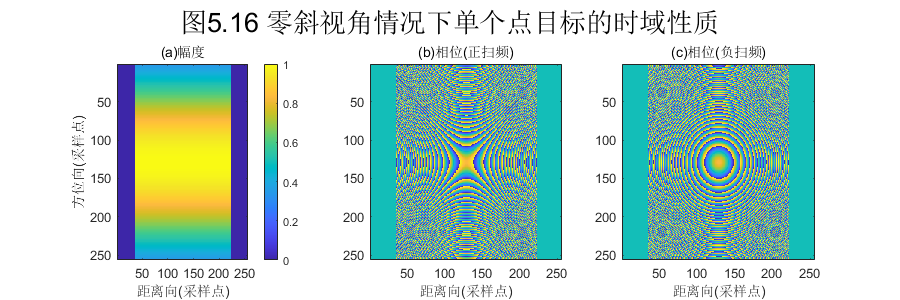

%  距离时域-方位频域
Srf_rd = fft(srt);
%  距离频域-方位频域
SrF_2d = fft2(srt);
%% 绘图
%  距离时域-方位时域
H1 = figure();
set(H1,'position',[100,100,900,300]);                    
subplot(131),imagesc(abs(srt_z)),colorbar               % 使用经过标度映射的颜色的图像
%{
imagesc(C)将数组C中的数据显示为一个图像，该图像使用颜色图中的全部颜色。
C(m,n)的每个元素指定图像的一个像素的颜色，生成的是一个mxn的像素网络。
%}
xlabel('距离向(采样点)'),ylabel('方位向(采样点)'),title('(a)幅度');
subplot(132),imagesc(angle(srt_z))
xlabel('距离向(采样点)'),title('(b)相位(正扫频)');
subplot(133),imagesc(angle(srt_f))
xlabel('距离向(采样点)'),title('(c)相位(负扫频)');
sgtitle('图5.16 零斜视角情况下单个点目标的时域性质','Fontsize',20,'color','k')

图5.16(b)和图5.16(c)中多出来的“鞍点”和“靶点”表明相位等值线存在虚像，这是因为缠绕状态的相位只代表复数信号的部分信息，故仅给出相位图就等价于将复数信号表示成实数信号，因而出现了虚像。

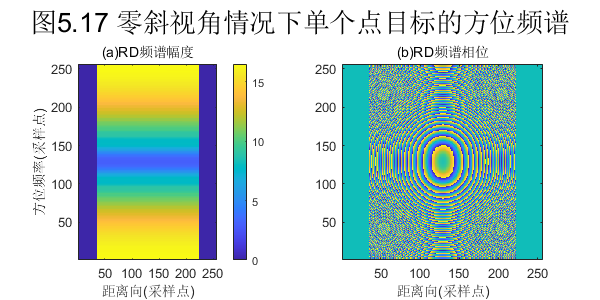

%  距离时域-方位频域
H2 = figure();
set(H2,'position',[100,100,600,300]);                    
subplot(121),imagesc(abs(Srf_rd)),colorbar               % 使用经过标度映射的颜色的图像
set(gca, 'YDir', 'normal')
%{
imagesc(C)将数组C中的数据显示为一个图像，该图像使用颜色图中的全部颜色。
C(m,n)的每个元素指定图像的一个像素的颜色，生成的是一个mxn的像素网络。
%}
xlabel('距离向(采样点)'),ylabel('方位频率(采样点)'),title('(a)RD频谱幅度');
subplot(122),imagesc(angle(Srf_rd)),set(gca, 'YDir', 'normal')
xlabel('距离向(采样点)'),title('(b)RD频谱相位');
sgtitle('图5.17 零斜视角情况下单个点目标的方位频谱','Fontsize',20,'color','k')

间隙就是处理中方位不连续频率所处的位置，也是方位过采样的体现。

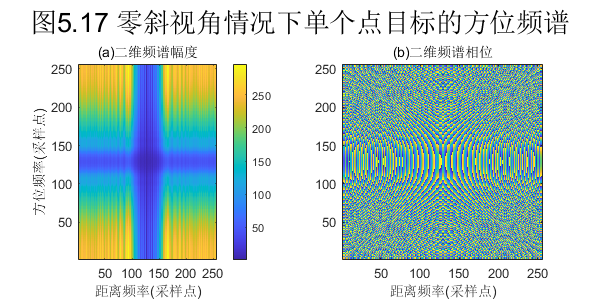

%  距离频域-方位频域
H3 = figure();
set(H3,'position',[100,100,600,300]);                    
subplot(121),imagesc(abs(SrF_2d)),colorbar               % 使用经过标度映射的颜色的图像
set(gca, 'YDir', 'normal')
%{
imagesc(C)将数组C中的数据显示为一个图像，该图像使用颜色图中的全部颜色。
C(m,n)的每个元素指定图像的一个像素的颜色，生成的是一个mxn的像素网络。
%}
xlabel('距离频率(采样点)'),ylabel('方位频率(采样点)'),title('(a)二维频谱幅度');
subplot(122),imagesc(angle(SrF_2d)),set(gca, 'YDir', 'normal')
xlabel('距离频率(采样点)'),title('(b)二维频谱相位');
sgtitle('图5.17 零斜视角情况下单个点目标的方位频谱','Fontsize',20,'color','k')

若$K_a>0

$，$K_r>0

$，则有：

距离时域方位时域

$\alpha_{const}=-\pi K_a\eta^2+\pi K_r\tau^2$         双曲线形式

距离频域方位时域

$\alpha_{const}=\pi\frac{f_{\eta}^2}{K_a}+\pi K_r\tau^2$              椭圆形式

距离频域方位频域

$\alpha_{const}=\alpha_{const}=\pi\frac{f_{\eta}^2}{K_a^{'}}-\pi\frac{f_{\tau}^2}{K_r}$    双曲线形式

无论是方位向傅里叶变换还是距离向傅里叶变换，都会改变二次相位的符号。

**非零斜视角情况**

解调后单个点目标的基带信号：


$$s_0(\tau,\eta)=A_0
                        \omega_r\left(\tau-\frac{2R(\eta)}{c}\right)
                        \omega_a(\eta-\eta_c)
                        \exp\left\{ -j4\pi\frac{f_0R(\eta)}{c} \right\}
                        \exp\left\{ j\pi K_r\left(\tau-\frac{2R(\eta)}{c}\right)^2 \right\}$$


$T_a=0.886\frac{\lambda R(\eta_c)}{L_aV_g\cos\theta_{r,c}}$，$K_a=\frac{2V_r^2\cos^2\theta_{r,c}}{\lambda R(\eta_c)}$。


$$R(\eta)=\sqrt{R_0^2+V_r^2\eta^2}$$



$$\omega_r\left(\tau-\frac{2R(\eta)}{c}\right)=rect\left(\frac{\tau-2R(\eta)/c}{T_r}\right)$$



$$\omega_a(\eta-\eta_c)=sinc^2\left[0.886\frac{\theta_{r,c}}{\theta_{bw}}\right]=sinc^2\left[0.886\frac{\arctan(V_g(\eta-\eta_c)/R_0)}{\theta_{bw}}\right]$$


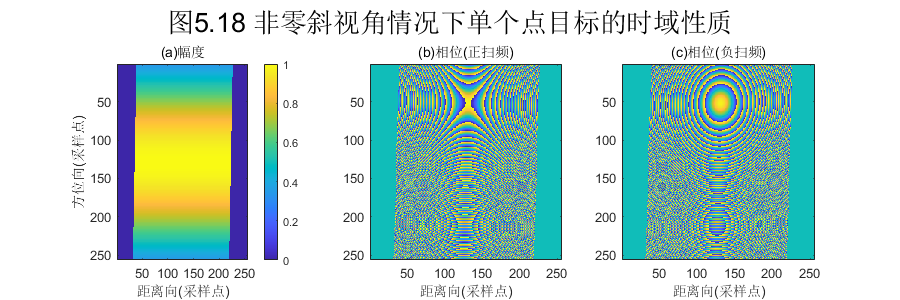

clc
clear
close all
%% 参数设置
%  已知参数--》距离向参数
R_eta_c = 20e+3;                % 景中心斜距
Tr = 25e-6;                     % 发射脉冲时宽
Kr = 0.25e+12;                  % 距离向调频率
alpha_os_r = 1.2;               % 距离过采样率
Nrg = 256;                      % 距离线采样点数
%  计算参数--》距离向参数
Bw = abs(Kr)*Tr;                % 距离信号带宽
Fr = alpha_os_r*Bw;             % 距离向采样率
%  已知参数--》方位向参数
c = 3e+8;                       % 电磁传播速度
Vr = 150;                       % 等效雷达速度
Vs = Vr;                        % 卫星平台速度
Vg = Vr;                        % 波束扫描速度
f0 = 5.3e+9;                    % 雷达工作频率
Delta_f_dop = 80;               % 多普勒带宽
alpha_os_a = 1.3;               % 方位过采样率
Naz = 256;                      % 距离线数
theta_r_c = [0,-22.8]*pi/180;   % 波束斜视角
t_eta_c = [0,-51.7];            % 波束中心穿越时刻
%{
t_eta_c = -R_eta_c*sin(theta_r_c(2))/Vr
%}
f_eta_c = [0,+2055];            % 多普勒中心频率
%  计算参数--》方位向参数
lambda = c/f0;                  % 雷达工作波长
Fa = alpha_os_a*Delta_f_dop;    % 方位向采样率
%  参数计算
R0 = R_eta_c*cos(theta_r_c(2));                         % 最短斜距
La = 0.886*2*Vs*cos(theta_r_c(2))/Delta_f_dop;          % 实际天线长度
theta_bw = 0.886*lambda/La;                             % 方位向3dB波束宽度
Trr = Nrg/Fr;                   % 发射脉冲时宽
Taa = Naz/Fa;                   % 目标照射时间
Ka = 2*Vr^2*cos(theta_r_c(2))^2/lambda/R0;              % 方位向调频率
d_t_tau = 1/Fr;                 % 距离采样时间间隔
d_t_eta = 1/Fa;                 % 方位采样时间间隔
d_f_tau = Fa/Nrg;               % 距离采样频率间隔    
d_f_eta = Fa/Naz;               % 方位采样频率间隔
%% 变量设置
%  时间变量                                                    
t_tau = (-Trr/2:d_t_tau:Trr/2-d_t_tau) + 2*R_eta_c/c;   % 距离时间变量
t_eta = (-Taa/2:d_t_eta:Taa/2-d_t_eta) + t_eta_c(2);    % 方位时间变量
%{
t_tau = (-Nrg/2:Nrg/2-1)/Fr + 2 * R_eta_c/c;            % 距离时间变量
t_eta = (-Naz/2:Naz/2-1)/Fa + t_eta_c(2);               % 方位时间变量
%}
%  坐标设置
%{
[X,Y] = meshgrid(x,y)是基于向量x和向量y中包含的坐标返回二维网络坐标。
 X是一个矩阵，每一行是x的一个副本；
 Y是一个矩阵，每一列是y的一个副本；
 坐标X和Y表示的网络有length(y)个行和length(x)个列。
%}                                                                                                             
[t_tauX,t_eta_Y] = meshgrid(t_tau,t_eta);               % 设置二维网络坐标
%% 信号设置
R_eta = sqrt(R0^2 + Vr^2*t_eta_Y.^2);                   % 瞬时斜率
%{
R_eta = R0 + Vr^2*t_eta_Y.^2/(2*R0);                    % 瞬时斜率
%}
A0 = 1;                                                 % 后向散射系数幅度
wr = (abs(t_tauX-2*R_eta/c) <= Tr/2);                   % 距离向包络
%{
距离向包络为矩形窗，因此可以观察到信号幅度图在距离向是均匀的，
但是严格的矩形窗也导致了幅度图和相位图在左右两侧均出现0值区域。
%}
wa = sinc(0.886*atan(Vg*(t_eta_Y-t_eta_c(2))/R0)/theta_bw).^2;      % 方位向包络
%{
方位向包络为sinc^2()的形式，因此可以观察到信号幅度图在方位向上
中心最强，而两侧的强度以sinc^2()的形式衰减。
%}
%  接收信号
srt = A0*wr.*wa.*exp(-1j*4*pi*f0*R_eta/c)...
               .*exp(+1j*pi*Kr*(t_tauX-2*R_eta/c).^2); 
%{
srt = A0*wr.*wa.*exp(-1j*4*pi*R0/lambda)...
               .*exp(-1j*pi*Ka*t_eta_Y.^2)...
               .*exp(+1j*pi*Kr*(t_tauX-2*R_eta/c).^2);
%}                                                          
srt_z = A0*wr.*wa.*exp(-1j*4*pi*f0*R_eta/c)...              
                 .*exp(+1j*pi*Kr*(t_tauX-2*R_eta/c).^2);% 正扫频
srt_f = A0*wr.*wa.*exp(-1j*4*pi*f0*R_eta/c)... 
                 .*exp(-1j*pi*Kr*(t_tauX-2*R_eta/c).^2);% 负扫频
%  距离时域-方位频域
Srf_rd = fft(srt);
%  距离频域-方位频域
SrF_2d = fft2(srt);
%% 绘图
%  距离时域-方位时域
H1 = figure();
set(H1,'position',[100,100,900,300]);                    
subplot(131),imagesc(abs(srt_z)),colorbar               % 使用经过标度映射的颜色的图像
%{
imagesc(C)将数组C中的数据显示为一个图像，该图像使用颜色图中的全部颜色。
C(m,n)的每个元素指定图像的一个像素的颜色，生成的是一个mxn的像素网络。
%}
xlabel('距离向(采样点)'),ylabel('方位向(采样点)'),title('(a)幅度');
subplot(132),imagesc(angle(srt_z))
xlabel('距离向(采样点)'),title('(b)相位(正扫频)');
subplot(133),imagesc(angle(srt_f))
xlabel('距离向(采样点)'),title('(c)相位(负扫频)');
sgtitle('图5.18 非零斜视角情况下单个点目标的时域性质','Fontsize',20,'color','k')

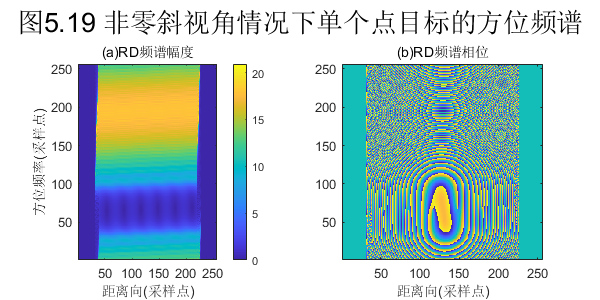

%  距离时域-方位频域
H2 = figure();
set(H2,'position',[100,100,600,300]);                    
subplot(121),imagesc(abs(Srf_rd)),colorbar,set(gca, 'YDir', 'normal')  
%{
imagesc(C)将数组C中的数据显示为一个图像，该图像使用颜色图中的全部颜色。
C(m,n)的每个元素指定图像的一个像素的颜色，生成的是一个mxn的像素网络。
%}
xlabel('距离向(采样点)'),ylabel('方位频率(采样点)'),title('(a)RD频谱幅度');
subplot(122),imagesc(angle(Srf_rd)),set(gca, 'YDir', 'normal')
xlabel('距离向(采样点)'),title('(b)RD频谱相位');
sgtitle('图5.19 非零斜视角情况下单个点目标的方位频谱','Fontsize',20,'color','k')

由于多普勒中心的改变，方位频率的间隙位置产生了移动。

根据$\Delta f_{dop}=0.886\frac{2V_s\cos\theta_{r,c}}{L_a}$，多普勒带宽按波束斜视角的余弦值被缩小，所以此处的间隙变大。

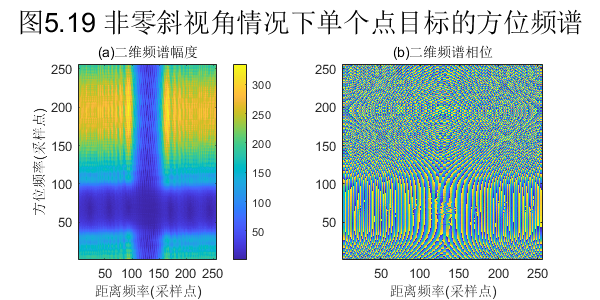

%  距离频域-方位频域
H3 = figure();
set(H3,'position',[100,100,600,300]);                    
subplot(121),imagesc(abs(SrF_2d)),colorbar,set(gca, 'YDir', 'normal')             
%{
imagesc(C)将数组C中的数据显示为一个图像，该图像使用颜色图中的全部颜色。
C(m,n)的每个元素指定图像的一个像素的颜色，生成的是一个mxn的像素网络。
%}
xlabel('距离频率(采样点)'),ylabel('方位频率(采样点)'),title('(a)二维频谱幅度');
subplot(122),imagesc(angle(SrF_2d)),set(gca, 'YDir', 'normal')
xlabel('距离频率(采样点)'),title('(b)二维频谱相位');
sgtitle('图5.19 非零斜视角情况下单个点目标的方位频谱','Fontsize',20,'color','k')